## See also (in Python): [https://colab.research.google.com/drive/14Ws9gX1hPzBkE7P1sBepVuoz-uo2f-Be?usp=sharing#scrollTo=cEbiyY7g_laK](https://colab.research.google.com/drive/14Ws9gX1hPzBkE7P1sBepVuoz-uo2f-Be?usp=sharing#scrollTo=cEbiyY7g_laK)

## Synthèse d'une sinusoïde de fréquence 100 Hz

clc;
figure;
subplot(1, 1, 1);

## Computation of the sinewave and display

fs = 16000; % Sampling Freq.
dur = 3; % Sound duration in s.
t = linspace(0, dur, dur*fs);
freq = 220;
amp = 1;
phase = 0;

snd = amp .* sin(2*pi*freq.*t + phase);
t = t';
snd = snd';
% Ramp the sound extremities
snd = zeroends(snd, fs);

plot(t, snd);

### Display of a subset (N periods) that is outside the ramping parts

nperiods = 5;
start = 100;
select = round((start*((fs/freq))):((start+nperiods)*((fs/freq))));

figure;
subplot(1, 1, 1);
plot(t(select), snd(select));

## Play and save the sound wave

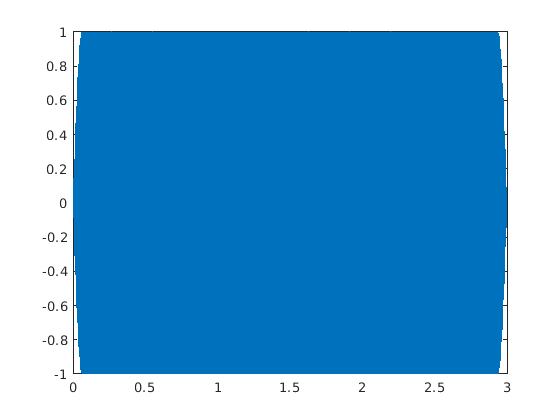

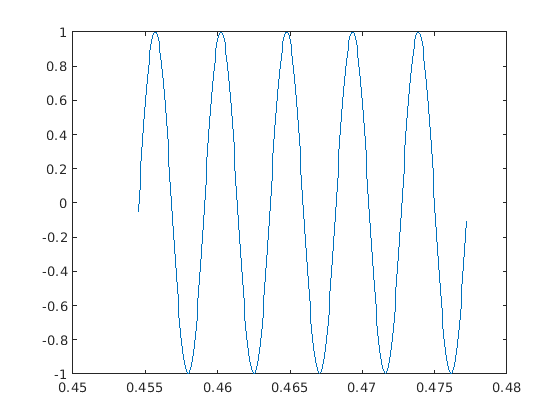

%soundsc(snd, fs);
%pause(dur);

listen = audioplayer(snd, fs);
playblocking(listen);

## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

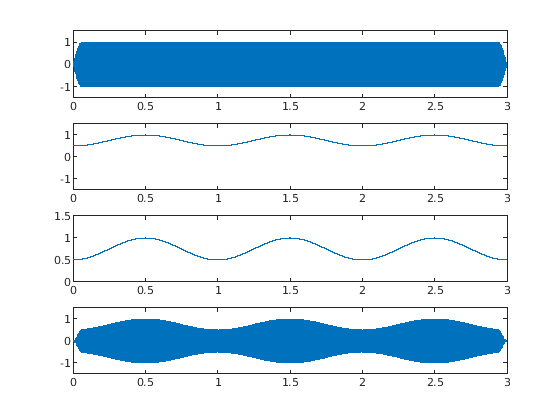

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Restriction à une période de l'enveloppe

extract = final(1:(AMf1*fs));
listen = audioplayer(extract, fs);
playblocking(listen);


## Generate an amplitude modulation: 6 Hertz (6 cycles par seconde, Sinewave AM)

AMf1 = 6; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

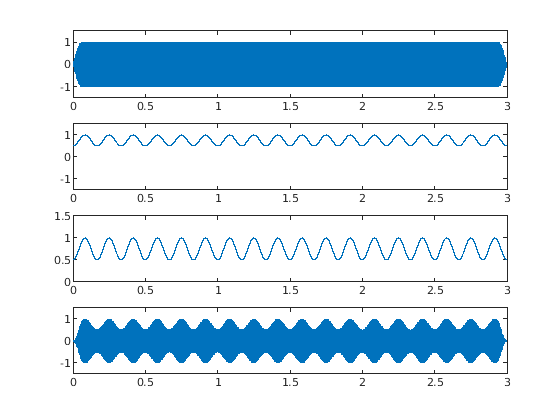

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Restriction à une période de l'enveloppe

extract = final(1:round(1/AMf1*fs));
listen = audioplayer(extract, fs);
playblocking(listen);


## Generate a multiple frequency amplitude modulation: 1 and 12 Hertz (1 and 12 cycles par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
AMf2 = 12; % Amplitude modulation frequency in Hertz
AMdepth2 = 0.75; % AM depth as a proportion of the carrier amplitude
AMphase2 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1) + 1/2*AMdepth2 .* cos(2*pi*AMf2.*t + AMphase2);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

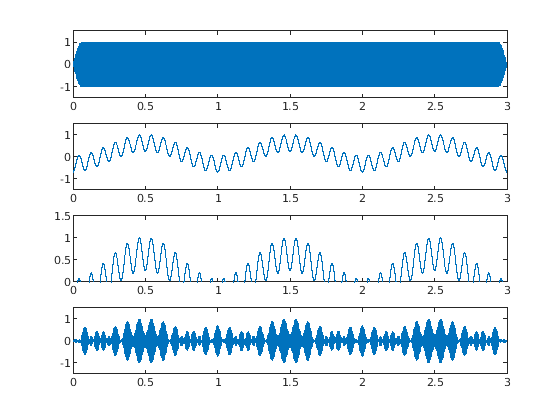

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);

## Computation of the amplitude modulation spectrum (using the Voicebox toolbox)

addpath('~/work/src/github/others/voicebox/sap-voicebox/voicebox')
%target = final; % Better use it on speech...
[speech, sfs] = audioread('~/work/sounds/databases/lscp/french/frl1151.aiff');
[c,qq,ff,tt,po] = v_modspect(speech, sfs, 'gMALfS');

## Computation of the amplitude modulation spectrum (using the AAA (Acoustics, Auditory and A1 Cortex) toolbox, cf. paper by Ediz Sohoglu, Essex University, on AM freq. LP filtering)

La toolbox est disponible à l'adresse [http://nsl.isr.umd.edu/downloads.html](http://nsl.isr.umd.edu/downloads.html) (named NSL Auditory Cortical toolbox on this page).

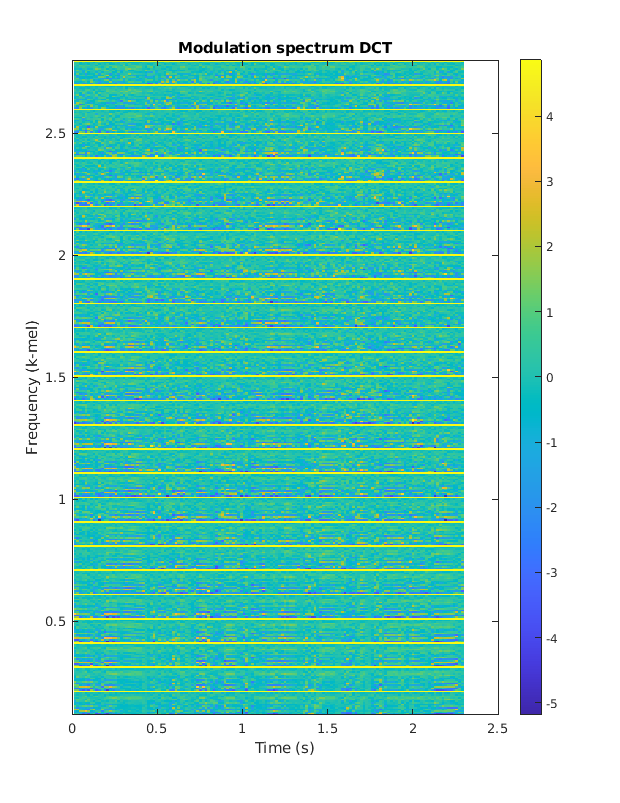

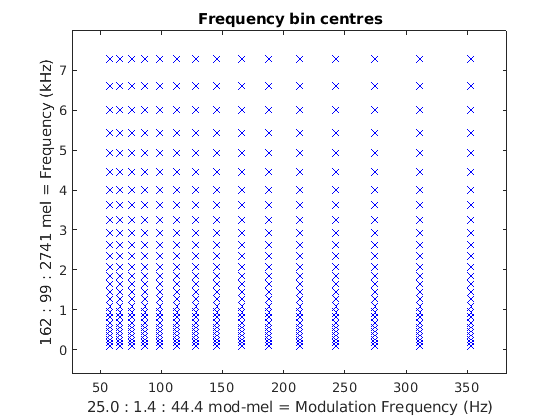

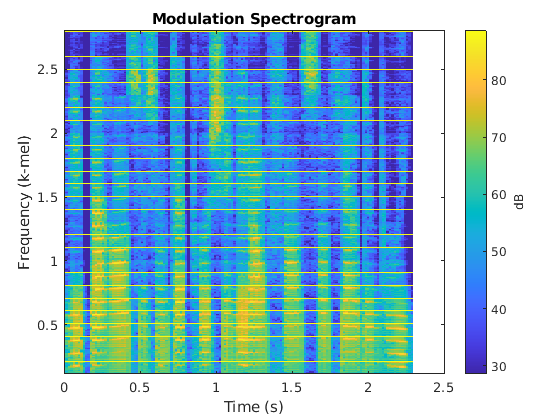

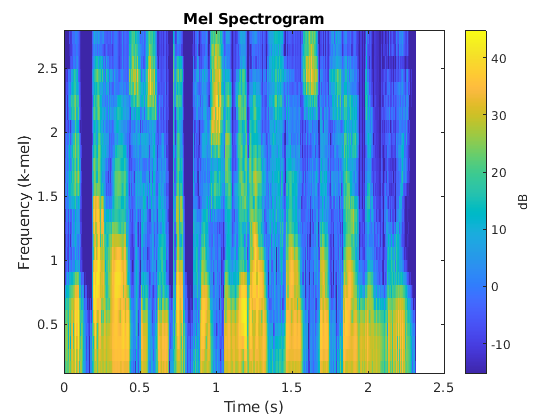

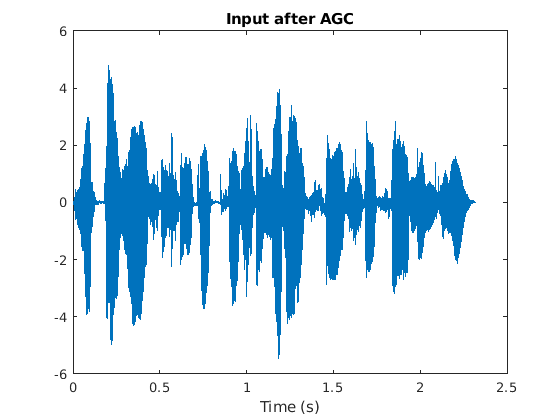

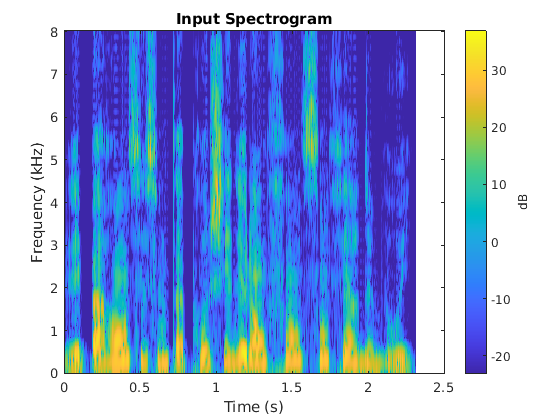

GENERATING CORTICAL FILE
 25.0% processed; elaps. 0:0: 0.2; esti. 0:0: 0.7; rem. 0:0: 0.5; 
 50.0% processed; elaps. 0:0: 0.3; esti. 0:0: 0.5; rem. 0:0: 0.3; 
 75.0% processed; elaps. 0:0: 0.4; esti. 0:0: 0.5; rem. 0:0: 0.1; 
100.0% processed; elaps. 0:0: 0.5; esti. 0:0: 0.5; rem. 0:0: 0.0; 


RECONSTRUCTING AUDITORY SPECTRUM
 25.0% processed; elaps. 0:0: 0.2; esti. 0:0: 0.6; rem. 0:0: 0.5; 
 50.0% processed; elaps. 0:0: 0.3; esti. 0:0: 0.6; rem. 0:0: 0.3; 
 75.0% processed; elaps. 0:0: 0.5; esti. 0:0: 0.6; rem. 0:0: 0.2; 
100.0% processed; elaps. 0:0: 0.6; esti. 0:0: 0.6; rem. 0:0: 0.0; 


RECONSTRUCTING WAVEFORM
#1, Err.: 99.83% (rel.); 168.62% (abs.); Energy: 4.4e+03
CPU: 0.53; 	ETIME: 0.2577 sec.
#2, Err.: 40.58% (rel.); 54.00% (abs.); Energy: 7.0e+03
CPU: 0.88; 	ETIME: 0.28153 sec.
#3, Err.: 29.29% (rel.); 40.11% (abs.); Energy: 7.4e+03
CPU: 1.15; 	ETIME: 0.27709 sec.
#4, Err.: 24.19% (rel.); 35.88% (abs.); Energy: 7.4e+03
CPU: 2.38; 	ETIME: 0.51327 sec.
#5, Err.: 21.56% (rel.); 34.07% (abs.); Energy: 7.5e+03
CPU: 6.07; 	ETIME: 1.3553 sec.
#6, Err.: 19.92% (rel.); 33.04% (abs.); Energy: 7.6e+03
CPU: 11.68; 	ETIME: 2.9767 sec.
#7, Err.: 18.77% (rel.); 31.94% (abs.); Energy: 7.7e+03
CPU: 10.18; 	ETIME: 2.6677 sec.
#8, Err.: 17.58% (rel.); 30.89% (abs.); Energy: 7.7e+03
CPU: 8.71; 	ETIME: 2.2498 sec.
#9, Err.: 16.18% (rel.); 30.03% (abs.); Energy: 7.6e+03
CPU: 1.64; 	ETIME: 0.40709 sec.
#10, Err.: 15.12% (rel.); 29.56% (abs.); Energy: 7.6e+03
CPU: 1.77; 	ETIME: 0.34118 sec.
Minimum Error: 15.12%


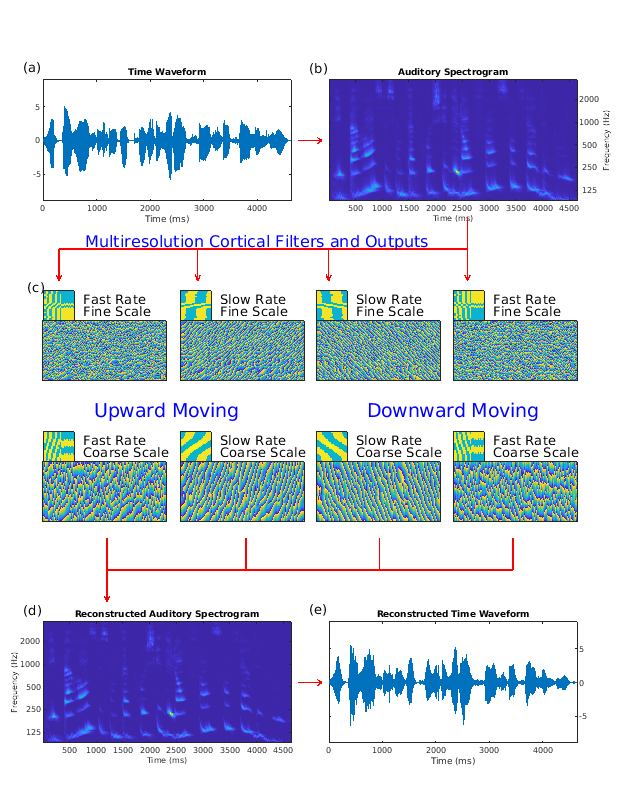

addpath('work/lib/matlab/contrib/AAA');
loadload;
%[x, fs] = audioread('_come.au');
x = speech;
x = unitseq(x); % ?? on x or on xh?
xh = schematc(x);

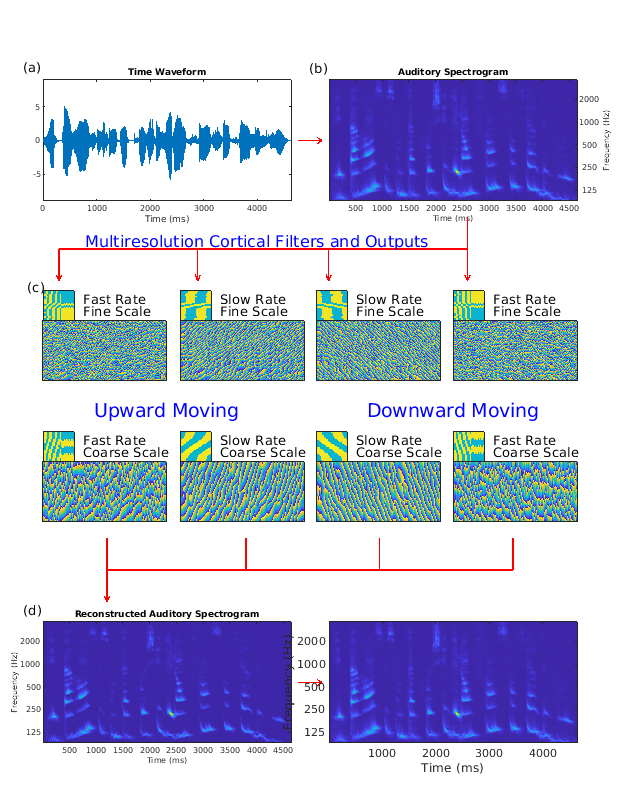


y = wav2aud(x, paras);
aud_plot(y, paras);

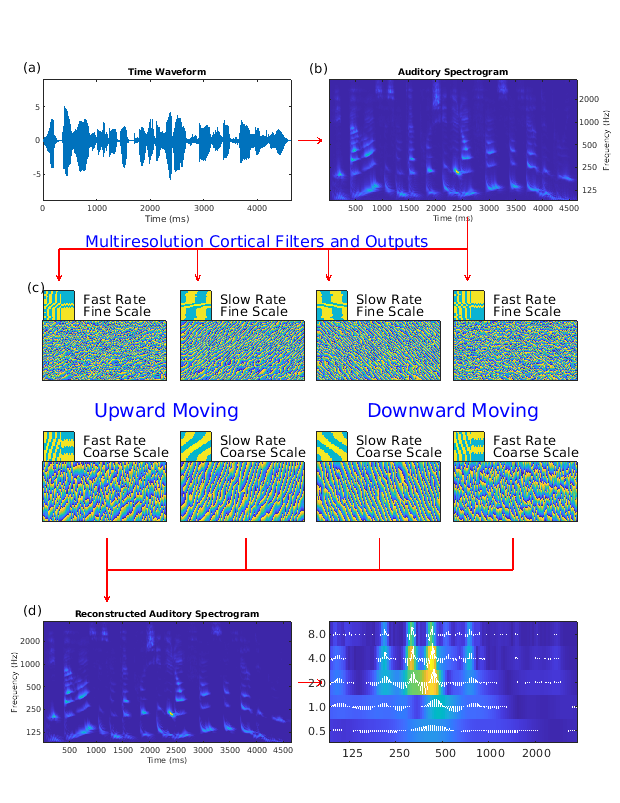



z = aud2cors(y(60,:), sv);
cor_plts(z, sv, paras);


fcorname = '_come.cor';
cr = aud2cor(y, paras, rv, sv, fcorname);

 25.0% processed; elaps. 0:0: 0.3; esti. 0:0: 1.4; rem. 0:0: 1.0; 
 50.0% processed; elaps. 0:0: 0.7; esti. 0:0: 1.4; rem. 0:0: 0.7; 
 75.0% processed; elaps. 0:0: 1.2; esti. 0:0: 1.6; rem. 0:0: 0.4; 
100.0% processed; elaps. 0:0: 1.9; esti. 0:0: 1.9; rem. 0:0: 0.0; 



rst = cor2rst(fcorname);

 25.0% processed; elaps. 0:0: 1.0; esti. 0:0: 4.1; rem. 0:0: 3.0; 
 50.0% processed; elaps. 0:0: 1.8; esti. 0:0: 3.6; rem. 0:0: 1.8; 
 75.0% processed; elaps. 0:0: 2.6; esti. 0:0: 3.5; rem. 0:0: 0.9; 
100.0% processed; elaps. 0:0: 3.5; esti. 0:0: 3.5; rem. 0:0: 0.0; 


rst_view(rst, rv, sv);

Max: 1.4e+00; Mean: 1.4e-01


colormap(jet);
rst_view(rst, rv, sv);

Max: 1.4e+00; Mean: 1.4e-01


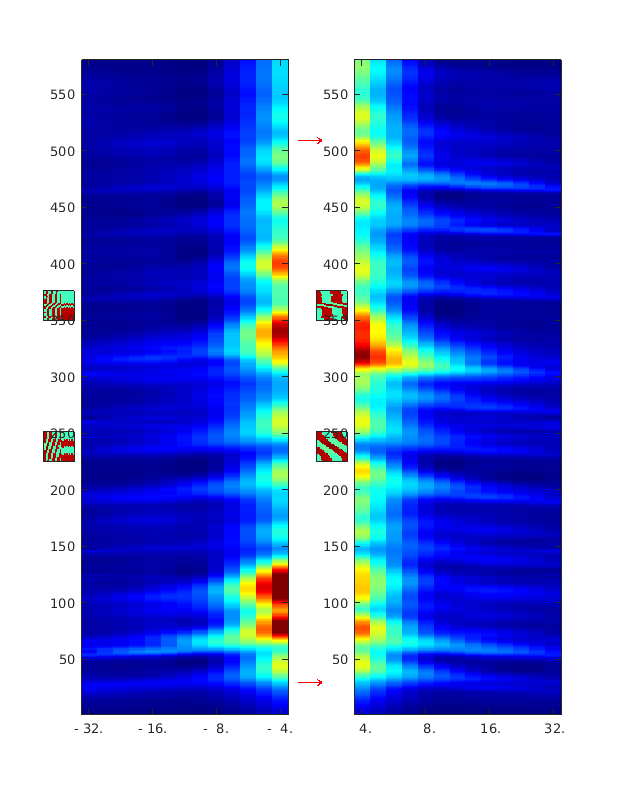

Max: 8.9e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 1);

Max: 4.0e-01; Mean: 1.4e-01


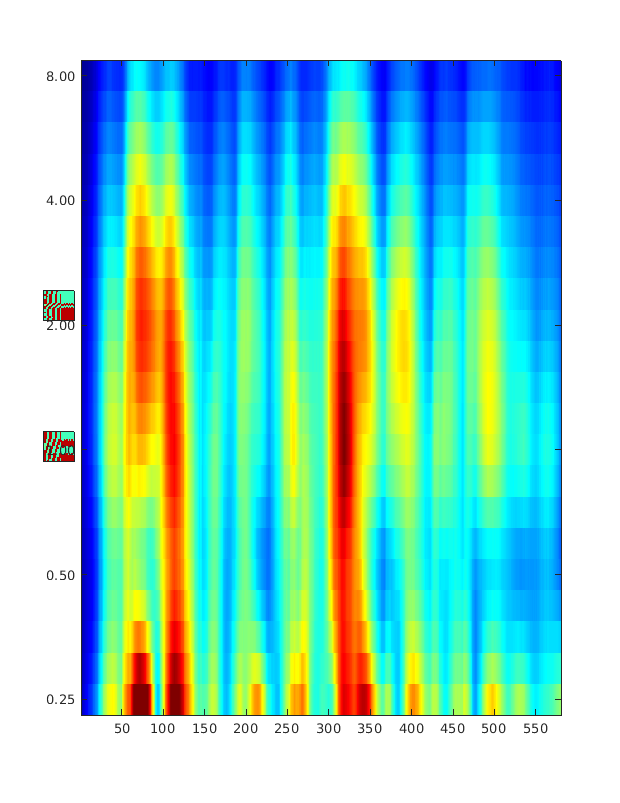

rst_view(rst, rv, sv, 2);

rst_view(rst, rv, sv, 3);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.5);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.9);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.75);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.5, 0);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.5, 1);

Max: 6.1e-01; Mean: 1.4e-01


rst_view(rst, rv, sv, 3, 0.5, 2);

Max: 6.1e-01; Mean: 1.4e-01



rst_view(rst, rv, sv, 0, 0.5, 2);

Max: 1.4e+00; Mean: 1.4e-01


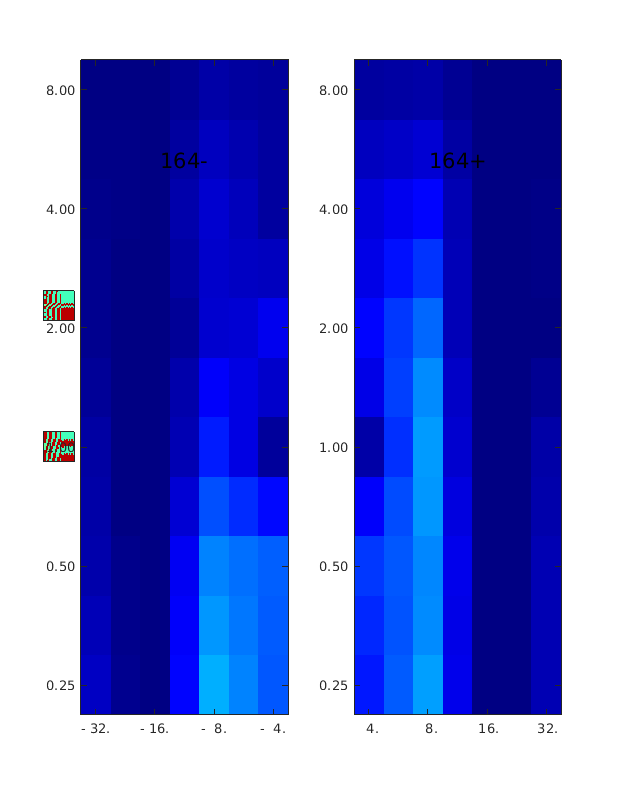

Max: 1.4e+00; Mean: 1.4e-01


rst_view(rst, rv, sv, 0, 1, 2);

rst_view(rst, rv, sv, 0, 1, 1);

Max: 1.4e+00; Mean: 1.4e-01


rst_view(rst, rv, sv, 0, 1, 0);

Max: 1.4e+00; Mean: 1.4e-01


rst_view(rst, rv, sv, 0, 1, 3);

Max: 1.4e+00; Mean: 1.4e-01


rst_view(rst, rv, sv, 0, 1, 0);

Max: 1.4e+00; Mean: 1.4e-01


rst_view(rst, rv, sv, 0, 1, 0, 1);

Max: 1.4e+00; Mean: 1.4e-01


Error using subplot (line 176)
Index must be a 3-digit number of the format mnp.

Error in rst_view (line 105)
		subplot(h_sub(sgdx));

rst_view(rst, rv, sv, 0, 1, 0, 2);
rst_view(rst, rv, sv, 0, 1, 0, 0);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 1, 3);
rst_view(rst, rv, sv, 0, 1, 2);
rst_view(rst, rv, sv, 0, 1, 1);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 0, 0);
rst_view(rst, rv, sv, 0, 1, 0);
rst_view(rst, rv, sv, 0, 2, 0);

rst_view(rst, rv, sv, 1, 1, 0);

rst_view(rst, rv, sv, 2, 1, 0);

rst_view(rst, rv, sv, 3, 1, 0);
rst_view(rst, rv, sv, 3, 0.1, 0);
rst_view(rst, rv, sv, 3, 0.5, 0);

h_sub = [subplot(121), subplot(122)]
h_sub(1)
h_sub(2)
subplot(121)
xlabel('Modulation Frequency (in Hz)');
ylabel('Conventional Frequency (in kHz)');

## Computation of the amplitude modulation spectrum (using tools from Columbia University that were inspired by Les Atlas' work)

La toolbox est disponible à l'adresse : [https://www.ee.columbia.edu/~marios/modspec/modcodec.html](https://www.ee.columbia.edu/~marios/modspec/modcodec.html) (le lien pour télécharger la toolbox est vers la fin de la section **Code** : [https://www.ee.columbia.edu/~marios/modspec/modcodec_2003_10_18.zip](https://www.ee.columbia.edu/~marios/modspec/modcodec_2003_10_18.zip).

addpath('~/work/learning/sigproc/ModulationSpectrum/modcodec')

% Define the hop lengths in milliseconds
fhop1ms = 10;
fhop2ms = 250;

% Convert from ms to samples
fhop1 = round(fhop1ms*sfs/1000);
fhop2 = round(fhop2ms*sfs/(fhop1*1000));

% Do the base transform
[fxdm,fxdp,fpad1] = basetran(speech,fhop1);

% Get the modulation spectrum
[fXc,fpad] = modspec(fxdm,fhop2);




## Generate a multiple frequency amplitude modulation: 1, 3 and 12 Hertz (1 and 12 cycles par seconde, Sinewave AM)

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
AMf2 = 6; % Amplitude modulation frequency in Hertz
AMdepth2 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase2 = 1*pi;
AMf3 = 12; % Amplitude modulation frequency in Hertz
AMdepth3 = 0.95; % AM depth as a proportion of the carrier amplitude
AMphase3 = 1*pi;
mod = 1/2*AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1) + 1/2*AMdepth2 .* cos(2*pi*AMf2.*t + AMphase2) + 1/2*AMdepth3 .* cos(2*pi*AMf3.*t + AMphase3);

% Compute effective modulation depending on depth
mod = mod + (1 - max(mod));

final = mod .* snd;
final = zeroends(final, fs);
%final = modulate(snd, AMf, fs, 'am');


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, mod);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);


## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde), Half-Wave Rectified AM

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 1*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% This is Full-Wave Rectification (1 cycle = 2 peaks)
%modFWR = abs(mod)./max(mod).*AMdepth1;
% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');

listen = audioplayer(final, fs);
playblocking(listen);


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])


## Generate an amplitude modulation: 1 Hertz (1 cycle par seconde), Profondeur de modulation 25%

AMf1 = 1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.25; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);


## Generate an amplitude modulation: 6 Hertz (6 cycles par seconde)

AMf1 = 6; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.25; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);


## Generate an amplitude modulation: 0.1 Hertz (0.1 cycle par seconde)

AMf1 = 0.1; % Amplitude modulation frequency in Hertz
AMdepth1 = 0.5; % AM depth as a proportion of the carrier amplitude
AMphase1 = 0*pi;
AMamp = AMdepth1 * amp;
mod = AMdepth1 .* cos(2*pi*AMf1.*t + AMphase1);

% Half-Wave Rectification (1 cycle = 1 peak)
hwr = mod>0;
modHWR = mod .* hwr;% ./max(mod).*AMdepth1;

% Compute effective modulation depending on depth
modHWR = modHWR + (1 - max(modHWR));

final = modHWR .* snd;
%final = modulate(snd, AMf, fs, 'am');


## Affichage

figure();
subplot(4, 1, 1);
plot(t, snd);
ylim([-1.5, 1.5])
subplot(4, 1, 2);
plot(t, mod);
ylim([-1.5, 1.5])
subplot(4, 1, 3);
plot(t, modHWR);
ylim([0, 1.5])
subplot(4, 1, 4);
plot(t, final);
ylim([-1.5, 1.5])

listen = audioplayer(final, fs);
playblocking(listen);


## Tests en cours (pas concluants pour l'instant)

Voir quelques scripts de Léo Varnet : [https://github.com/LeoVarnet/AM_FM_Spectra](https://github.com/LeoVarnet/AM_FM_Spectra)

### Computation of the amplitude modulation spectrum (using the AMA toolbox)

La toolbox Auditory Modulation Analysis (AMA) est disponible à l'adresse : [https://github.com/MuSAELab/amplitude-modulation-analysis-module](https://github.com/MuSAELab/amplitude-modulation-analysis-module)

Il existe aussi une version pour Python.

% Spectrogram (Time-Frequency)
target = final; %speech;

% Power using its PSD from rFFT
psd_rfft = rfft_psd(target, fs, [], 'blackmanharris');
f_step = psd_rfft.freq_axis(2);
power_psd_rfft = f_step * sum(psd_rfft.PSD);
%figure()
plot_psd_data(psd_rfft)

Les périodes associées aux 2 modulations d'amplitude sont:

AMf1
T1=1/AMf1
AMf2
T2=1/AMf2

Elles valent donc approximativement 0.1, 1 s en termes de période). Si on élargit la taille du déplacement de la fenêtre (w_shift), on améliore la détection des fréquences de modulation.

%% Power from STFFT Spectrogram (Hamming window)
%w_size =  2^nextpow2(0.02 * fs);
w_size =  2^nextpow2(0.2 * fs);
w_shift = 0.025 * w_size;
win_funct = 'hamming';
rfft_spect = strfft_spectrogram(target, fs, w_size, w_shift, [], win_funct );
power_spect = sum(sum(rfft_spect.power_spectrogram)) * rfft_spect.freq_delta * rfft_spect.time_delta;
%figure()
plot_spectrogram_data(rfft_spect);


%% Power from Modulation Spectrogram STFFT
rfft_mod = strfft_modulation_spectrogram(target, fs, w_size, w_shift, [], win_funct, [], win_funct);
power_mod = sum(sum(rfft_mod.power_modulation_spectrogram) * rfft_mod.freq_delta * rfft_mod.freq_mod_delta);
%figure()
plot_modulation_spectrogram_data(rfft_mod)

